clc;
clear all;
close all; 
NantTX = [256];
Sysparam = struct();
Sysparam.Nr = 4;
Sysparam.Ns = 4;
Sysparam.fc = 3e11;%carrier frequency 
Sysparam.f = 30e9; %bandwidth 
Sysparam.K = 129;  %number of sub-carriers
Sysparam.M = 16; %number of TTDs for each RF chain
Sysparam.L = 4; % number of paths equals to number of RF chains
% compute discrete time-delay values
Sysparam.Q = 64; % number of fixed TTD element 
Sysparam.tmax = (1e-12)*340;
Sysparam.T = Sysparam.tmax*(0:1:Sysparam.Q-1)/(Sysparam.Q-1);
% Sub-carrier frequencies
for k =1:Sysparam.K 
    Sysparam.F(k,1) = Sysparam.fc +(Sysparam.f/Sysparam.K)*(k-1-(Sysparam.K-1)/2); % sub-carrier frequency
end 
% relative frequencies
Sysparam.xi = Sysparam.F/Sysparam.fc; 
load SimParamPhi.mat
P = 3;
Rho = 10.^(P/10); %transmit power
%P = 1; 

%% Achievable rate comparison
Rate1 = zeros(Sysparam.K,length(NantTX)); % ideal Analog precoder
Rate4 = zeros(Sysparam.K,length(NantTX)); % Gao_design
Nrlz = 100; %number of channel realizations

SD = sin(Simparam.phi);%spaitlal directions

% Sysparam.Nt = NantTX(1);
% Sysparam.N = Sysparam.Nt/Sysparam.M;% number of PS per TTD 
% % Nt = Sysparam.Nt;
% % M = Sysparam.M; %% = V_TTD in the paper
% % % N = Sysparam.N;%% = M_T in the paper
% % L = Sysparam.L;
% % K = Sysparam.K;
% % F = Sysparam.F;
% % fc = Sysparam.fc;
% % tmax = Sysparam.tmax;
% % phi = Simparam.phi;
% %% generate time delay values
%    for l = 1:Sysparam.L
%         if sin(Simparam.phi(l)) > 0
%             for m = 1:Sysparam.M
%                 TTD_Gao(l,m) = (m-1)*(Sysparam.N)*sin(Simparam.phi(l))/(2*Sysparam.fc);
%                 if TTD_Gao(l,m) >= Sysparam.tmax
%                     TTD_Gao(l,m) = Sysparam.tmax;
%                 end
%             end
%         else
%             for m = 1:Sysparam.M
%                 TTD_Gao(l,m) = (Sysparam.M-1)*abs(Sysparam.N*sin(Simparam.phi(l)))/(2*Sysparam.fc) + (m-1)*(Sysparam.N*sin(Simparam.phi(1))/2)/Sysparam.fc;
%                 if TTD_Gao(l,m) >= Sysparam.tmax
%                    TTD_Gao(l,m) = Sysparam.tmax;
%                 end
%             end 
%         end
%    end

% %% TTD precoder
% F2k = zeros(Sysparam.M*Sysparam.L,Sysparam.L,Sysparam.K);
%     for k = 1:Sysparam.K
%       for l = 1:Sysparam.L
%           F2k((l-1)*Sysparam.M+1:l*Sysparam.M,l,k) =exp(-1j*2*pi*Sysparam.F(k).*TTD_Gao(l,:)); 
%       end 
%     end 

% %% generate additional phase  values
%  % MN = Nt
%     for l = 1:Sysparam.L
%         for m = 1:Sysparam.M
%                 z(l,m) = -pi*(m-1)*Sysparam.N*(sin(Simparam.phi(1))/2)*(Sysparam.f/Sysparam.fc); 
%         end 
%     end

%  %% generate phase values
%  % MN = Nt
%     for l = 1:Sysparam.L
%         for n = 1:Sysparam.N
%             for m = 1:Sysparam.M
%                 x(l,n,m) = -pi*((n-1)*Sysparam.M+m-1)*sin(Simparam.phi(l))/(2*Sysparam.fc)*(1+Sysparam.f/(2*Sysparam.fc));
%             end 
%         end 
%     end 
%    %% PS precoder
%     F1 = zeros(Sysparam.Nt,Sysparam.M*Sysparam.L);
%     for l = 1:Sysparam.L
%         G(:,:,l) = zeros(Sysparam.Nt,Sysparam.M);
%         for m = 1:Sysparam.M
%             G((m-1)*Sysparam.N+1:m*Sysparam.N,m,l) = exp(1j*pi.*x(l,:,m))*exp(-j*z(l,m)); 
%         end 
%         F1(:,(l-1)*Sysparam.M+1:l*Sysparam.M) = G(:,:,l)/sqrt(Sysparam.Nt); 
%     end 

% for k = 1:Sysparam.K
%     Analog(:,:,k) = F1*F2k(:,:,k);
% end 

for n =1:length(NantTX)
Sysparam.Nt = NantTX(n);
Sysparam.N = Sysparam.Nt/Sysparam.M;% number of PS per TTD 

%% Ideal Analog precoder
for l = 1:Sysparam.L
    %F3(:,l) = ArrResponseGenerateH(Sysparam.Nt,Simparam.phi(l),1)/sqrt(Sysparam.Nt);
    for k =1:Sysparam.K
        idealF(:,l,k) = ArrResponseGenerateH(Sysparam.Nt,Simparam.phi(l),Sysparam.xi(k))/sqrt(Sysparam.Nt);
    end 
end 
%% 
for nRlz = 1:Nrlz
    %% generate channel
    H = WidebandChannel(Sysparam,Simparam);   
    %% compensate beam squint
    [F1,F2k,x_Gao,TTD_Gao] = Gao_fixedPS_TD(Sysparam,Simparam); %Gao design
    %%  
    for k = 1:Sysparam.K
       %% ideal analog precoder
          Heff1(:,:,k) = H(:,:,k)*idealF(:,:,k);
          [~,~,Veff1(:,:,k)] = svd(Heff1(:,:,k));
          Rate1(k,n) = Rate1(k,n)+log2(det(eye(Sysparam.Ns)+(Rho/Sysparam.Ns)*Heff1(:,:,k)*Veff1(:,1:Sysparam.Ns,k)*Veff1(:,1:Sysparam.Ns,k)'*Heff1(:,:,k)'));         
          Heff4(:,:,k) = H(:,:,k)*F1*F2k(:,:,k);
         [~,~,Veff4(:,:,k)] = svd(Heff4(:,:,k));
         Rate4(k,n) = Rate4(n)+log2(det(eye(Sysparam.Ns)+(Rho/Sysparam.Ns)*Heff4(:,:,k)*Veff4(:,1:Sysparam.Ns,k)*Veff4(:,1:Sysparam.Ns,k)'*Heff4(:,:,k)'));    
    end  
end
clear idealF 
end 
%%
Rate1 = real(Rate1)./Nrlz;
Rate4 = real(Rate4)./Nrlz;
%% 

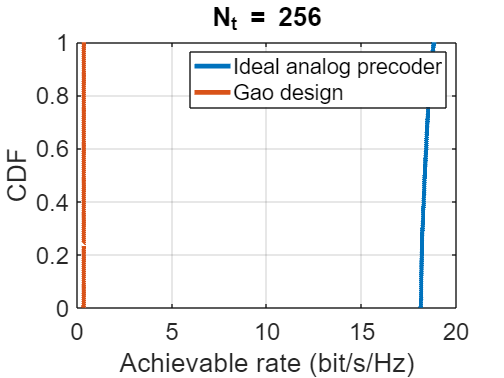

set(0, 'defaultlinelinewidth', 3); set(0, 'defaultlinemarkersize', 8);
set(0, 'defaultaxesfontsize', 20); set(0, 'defaulttextfontsize', 20); 
for n = 1:length(NantTX)
figure(n)
f1 = cdfplot(Rate1(:,n));
set(f1,'LineWidth',4,'LineStyle','-','Marker','none');
hold on
f4 = cdfplot(Rate4(:,n));
set(f4,'LineWidth',4,'LineStyle','-','Marker','none');
legend('Ideal analog precoder','Gao design')
xlabel('Achievable rate (bit/s/Hz)')
ylabel('CDF')
title("N_t = " + NantTX(n))
end 

%%